•Plotar as curvas características do dutycicleD em função de Io/Io,max.

•Valores de Vo/E: 4, 2 e 1.5.

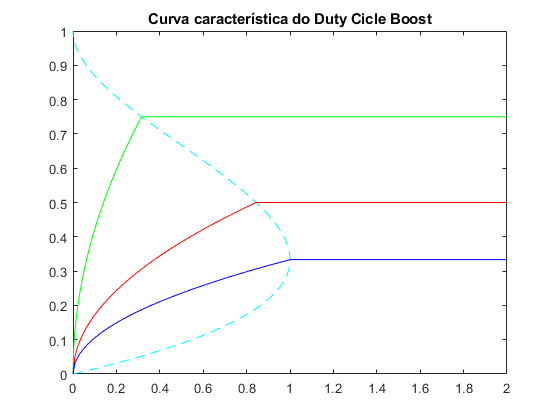

% Fronteira
% m = Vo/E
% n = Io/Io,max
D = linspace(0,1,100);
n = (27/4).*D.*(1-D).^2;
plot(n,D,'c--'); hold on;

% Descontínua
n = linspace(0,81/256,100);
m = 4;
D = sqrt((4/27)*m*(m-1)*n);
plot(n,D,'g'); hold on;

n = linspace(0,27/32,100);
m = 2;
D = sqrt((4/27)*m*(m-1)*n);
plot(n,D,'r'); hold on;

n = linspace(0,1,100);
m = 1.5;
D = sqrt((4/27)*m*(m-1)*n);
plot(n,D,'b'); hold on;

% Contínua
n = linspace(81/256,2,200);
for i = 1:200
    m(i) = 4;
    D(i) = 1 - m(i)^-1;
end
plot(n,D,'g'); hold on;

n = linspace(27/32,2,200);
for i = 1:200
    m(i) = 2;
    D(i) = 1 - m(i)^-1;
end
plot(n,D,'r'); hold on;

n = linspace(1,2,200);
for i = 1:200
    m(i) = 1.5;
    D(i) = 1 - m(i)^-1;
end
plot(n,D,'b'); hold on;
title('Curva característica do Duty Cicle Boost');